## **Worked Example 11.2**

 AERO60007 Control Systems 2024-2025

% Housekeeping
clear
clc
close all

% Input the dynamics matrix and calculate its eigenvalues
A = [0 1 0 0; -14 -10 4 4; 0 0 0 1; 2 2 -2 -2];
eig(A)

ans =   -9.3459 + 0.0000i
  -1.4711 + 0.0000i
  -0.5915 + 1.0511i
  -0.5915 - 1.0511i


jordan(A)

ans =   -9.3459 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -1.4711 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.5915 - 1.0511i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.5915 + 1.0511i



% Input the remaining matrices and create a state-space system
B = [0; 1; 0; 0];
C = [1 0 0 0];
D = [0];
sys = ss(A, B, C, D);

% Input the augmented open-loop system matrices and create a state-space system
A_o = [A ([0;0;0;0]) ; C 0]; 
B_o = [B ; 0]; 
C_o = [C 0]; 
D_o = [0]; 
sys_o = ss(A_o,B_o,C_o,D_o);

% Create a vector of desired eigenvalue locations
P = [-0.5 -1 (-1+2i) (-1-2i) -15]; 

% Calculate the vector of feedback gains
feedback_gains = -1*place(A_o,B_o,P);

% Separate the state-feedback gain 𝐾 and the integral gain 𝑘i
K = feedback_gains(1:4)

K =   -20.2500   -6.5000  -16.0000    0.1250


ki = feedback_gains(5)

ki = -18.7500


% Calculate the feedforward gain 𝑘r
kr = -1/(C*inv(A+B*K)*B)

kr = 46.2500

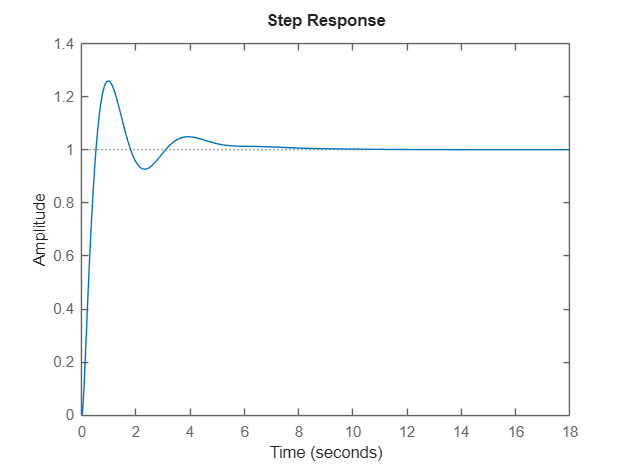


% Input the closed-loop system matrices and create a state-space system
Acl = A_o + B_o*[K ki]; 
Bcl = [B*kr ; -1]; 
Ccl = [C 0]; 
Dcl = [0]; 
sys_cl = ss(Acl,Bcl,Ccl,Dcl);

step(sys_cl, 18)

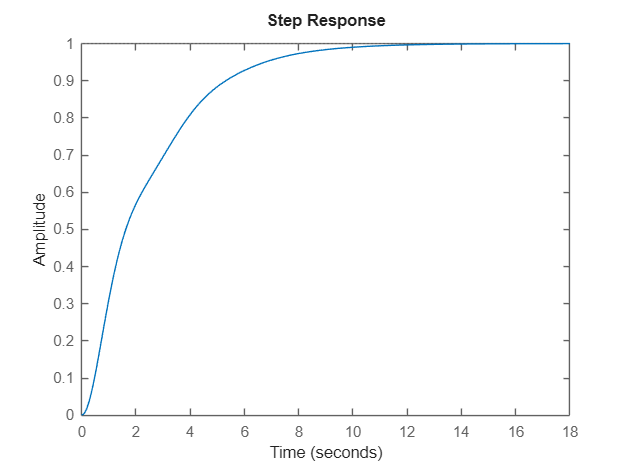


% Input the closed-loop system matrices and create a state-space system with just proportional control 
Acl2 = A_o + B_o*[K ki]; 
Bcl2 = [B*1 ; -1]; 
Ccl2 = [C 0]; 
Dcl2 = [0]; 
sys_cl2 = ss(Acl2,Bcl2,Ccl2,Dcl2); 

step(sys_cl2, 18)

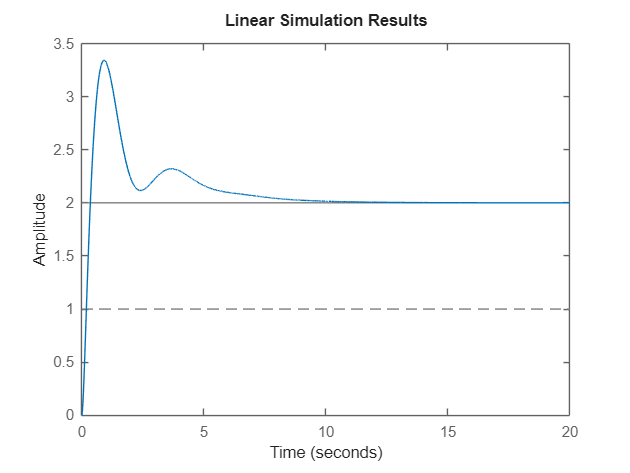


% Input the new closed-loop control matrix and create a state-space system
Bcl = [B*kr B; -1 0]; 
sys_cl = ss(Acl,Bcl,Ccl,Dcl); 

Acl2 = A_o + B_o*[K 0]; 
Bcl2 = [B*kr B; -1 0]; 
sys_cl2 = ss(Acl2,Bcl2,Ccl2,Dcl2);

% Create the time vector and input force matrix 
T = [0:0.001:20]; 
U = [2*ones(size(T)); ones(size(T))]; 

% Set the initial conditions for the closed-loop system
x0 = [0;0;0;0;-2];

% Simulate the closed-loop system 
lsim(sys_cl,U,T,x0) 

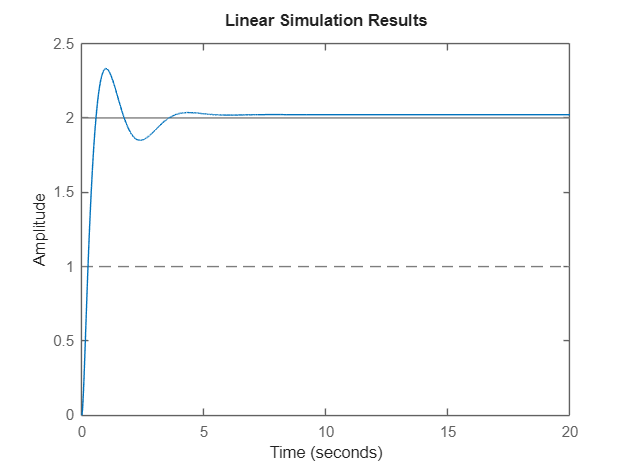

lsim(sys_cl2,U,T,x0) 